# FDTD for 2-D TE propagation

# 2B. Impressed source exciting a plane wave (1 hour)

In this third file, we will no more enforce initial boundary conditions corresponding to the field we want to compute. Instead, we will enforce a zero intial field and we will introduce an impressed source with PEC conditions on the four sides of the rectangle. The source will excite a standing wave.

We solve the time evolution of a the wave inside the same rectangular region of the previous file, the rectangle $[0,XL]\times[0,YL]$.

close all; clearvars

Let's put in the following empty code boxes the code written in the previous file.

We keep the same rectangular domain as before, but we use now 101 points along the $x$ direction.

## 1 Definition of fundamental variables

c   = 3d8;               % Light velocity in vacuum
mu0 = 4*pi*1.d-7;        % Vacuum magnetic permeability
eps0= 1.d-9/(36*pi);     % Vacuum dielectric permettivity

f = 30*1d9;              % Plane-wave frequency (10 GHz)
k_unit = [1 0];          % Unit vector for the plane-wave propagation direction
lambda = 3d8/f;          % Wavelength in vacuum
sigma =1;             % Conductivity, for question 9

## 2 Definition of the spatio-temporal grid

### 2.1 Definition of the spatio-temporal regions

XL = 25d-3 ;     % Total length of the domain in the x direction (in meters)
x0 = 0 ;     % Left boundary along x
YL = 5d-3 ;      % Total length of the domain in the y direction (in meters)
y0 = 0 ;      % Bottom boundary along y
TL = 0.1d-9;    % Duration of the simulation (in seconds)
t0 = 5;         % Initial time

### 2.2 Definition of the spatio-temporal grid

% Discretization
NX=101;              % number of cells along the x direction
NY=5;               % number of cells along the y direction
T=350;              % number of time intervals
Delta_x=XL/NX;      % Computing the x discretization step
Delta_y=YL/NY;      % Computing the y discretization step
Delta_t=TL/T;       % Computing the t discretization step

% Sampling instants
t_E = (0:T-1)*Delta_t;
t_H = t_E+Delta_t/2;

% Sampling points of Ex
x_Ex= (0:NX-1)*Delta_x + Delta_x/2;
y_Ex= (0:NY)*Delta_y;
[y_Ex_grid,x_Ex_grid] = meshgrid(y_Ex,x_Ex);

% Sampling points of Ey
x_Ey= (0:NX)*Delta_x;
y_Ey= (0:NY-1)*Delta_y + Delta_y/2;
[y_Ey_grid,x_Ey_grid] = meshgrid(y_Ey,x_Ey);

% Sampling points of Hz
x_Hz= (0:NX-1)*Delta_x + Delta_x/2;
y_Hz= (0:NY-1)*Delta_y + Delta_y/2;
[y_Hz_grid,x_Hz_grid] = meshgrid(y_Hz,x_Hz);

### 2.3 Visualization of the spatial grid

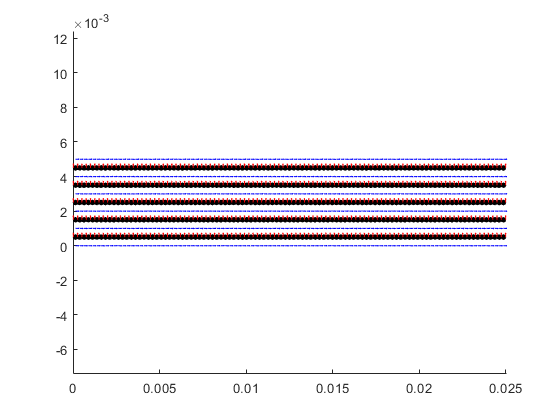

% Grid visualization
figure(1)
scatter( x_Hz_grid(:) , y_Hz_grid(:) ,18,'o','filled','k')
hold on
arrow_length = Delta_x/3;
quiver(x_Ex_grid,y_Ex_grid,ones(size(x_Ex_grid)),zeros(size(y_Ex_grid)),0.05,'b')
hold on
arrow_length = Delta_y/3;
quiver(x_Ey_grid,y_Ey_grid,zeros(size(x_Ey_grid)),ones(size(y_Ey_grid)),0.05,'r')
axis equal

## 4 Control of the stability condition

% Verifying the stability condition
Left= abs(1-2*(c*Delta_t/Delta_x)^2.*sin(k_unit*Delta_x/2));
Right= 1;
Left <= Right

ans = 1×2 logical array
   1   1


## 5 Definition of field variables

Let us now inizialize the fields to zero with the "zeros" command.

Each field should be a 2x2 matrix of correct dimensions. Check the dimensions of each component (they are different!) by looking at the dimensions of the matrices of the grids created in Section 3.

Ex= zeros(size(x_Ex_grid));
Ey= zeros(size(y_Ey_grid));
Hz= zeros(size(x_Hz_grid));

## 6 Definition of the impressed sources

Let us define a magnetic source $M_z(x,y;t)$placed on the segment $x=\frac{XL}{2}$ and  $0\leq y\leq YL$. For the moment, the source does not depend on the $y$ coordinate: $M_z = M_z(x;t)$

Due to its symmetry, this source will excite fields which do not depend on $y$: plane waves propagating on its right and on its left.

Let us write a function "magnetic_current.m" which computes the field of a standing plane wave:

    $    M_z = \cos(2 \pi f_0 t)   \quad \text{if } x=\frac{XL}{2} \text{ and } 0\leq y\leq YL$, in the interval  $0\leq t\leq 1.6571\cdot 10^{-2} \text{ ns}$

with $f_0 = 30 \text{ GHz}$. Notice that the interval $0\leq t\leq 1.6571\cdot 10^{-2} \text{ ns}$ corresponds to the first 58 points of the time samples.

Remember to sample the magnetic source at the correct spatial points and instants. In the code you should replace 'x points','y points','time' with the correct variables.

You can verify the definition by plotting the time evolution of the current (with a "plot" command).

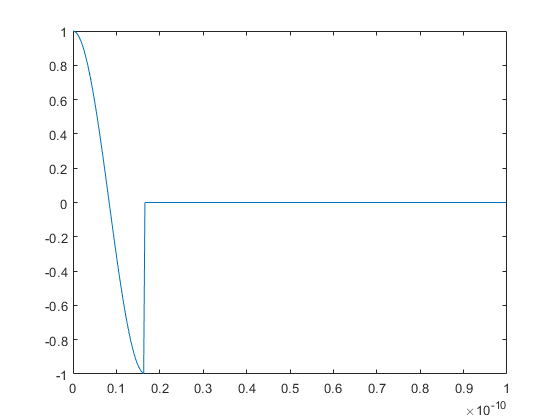


figure(2);
Mz(:,:,:) = magnetic_current(x_Hz,y_Hz,t_E,f,k_unit);
plot(t_E,squeeze(Mz(0.5*(length(x_Hz)+1),1,:)));
hold on

## 7 The FDTD algorithm: the time update with impressed sources

Now we need to modify the time update with the presence of a magnetic source.

Remember in which equation the magnetic current goes. The Maxwell equations with a magnetic current in 2-D read:

            
$$\mu_0\frac{\partial}{\partial t}H_z = \frac{\partial}{\partial y}E_x - \frac{\partial}{\partial x}E_y - M_z \\

\varepsilon_0\frac{\partial}{\partial t}E_x = \frac{\partial}{\partial y}H_z \\

\varepsilon_0\frac{\partial}{\partial t}E_y = -\frac{\partial}{\partial x}H_z \\$$


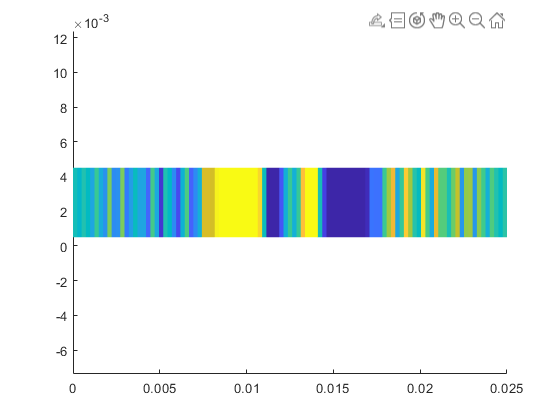

% Definition of the contants for the time update
const_ty_eps = Delta_t/(Delta_y*eps0) ;
const_tx_eps = Delta_t/(Delta_x*eps0) ;
const_ty_mu  = Delta_t/(Delta_y*mu0) ;
const_tx_mu  = Delta_t/(Delta_x*mu0) ;
const_sigma  = sigma*Delta_t/(2*eps0);

figure(5)
caxis([-3d-7 3d-7]) % Good color scale for the Hz video
% caxis([-2d-4 2d-4]) % Good color scale for the Ey video
hold on
set(gcf,'Visible','on')
axis equal
 
for time_instant=1:T
    
    % Boundary conditions on E
       
        % PEC boundary conditions at x=0 and at x=XL, y=0 and at y=YL : no need to update Ex and Ey (they stay zero)
        
    % E-field time update
        Ex(1:NX,2:NY)=((1-const_sigma)/(1+const_sigma))*Ex(1:NX,2:NY)+const_ty_eps*(Hz(1:NX,2:NY)-Hz(1:NX,1:NY-1))/(1+const_sigma);
        Ey(2:NX,1:NY)=((1-const_sigma)/(1+const_sigma))*Ey(2:NX,1:NY)-const_tx_eps*(Hz(2:NX,1:NY)-Hz(1:NX-1,1:NY))/(1+const_sigma);

    
    % H-field time update
        Hz(1:NX,1:NY)=Hz(1:NX,1:NY)-const_tx_mu*(Ey(2:NX+1,1:NY)-Ey(1:NX,1:NY))+const_ty_mu*(Ex(1:NX,2:NY+1)-Ex(1:NX,1:NY))-(Delta_t/mu0)*Mz(1:NX,1:NY,time_instant);

    
        
% Recording the frames for each field as in
    
   
   figure(5)
   h= pcolor(x_Ey_grid,y_Ey_grid,Ey);
   set(h, 'EdgeColor', 'none');
%     Ey_frames(time_instant) = getframe;
    
%     figure(5)
%     h= pcolor(x_Hz_grid,y_Hz_grid,Hz(:,:));
%     set(h, 'EdgeColor', 'none');
%     Hz_frames(time_instant) = getframe;
    
end 

## 8 Recording the field animation

Record the field computed at all the time instants in the file "Hz_impressed_source1.avi". Try to do the same for other field components (but you need to run again the simulation).

% writerObj = VideoWriter('Hz_impressed_source1.avi');  %Ey_impressed_source_source1.avi
% open(writerObj);
% writeVideo(writerObj, Hz_frames)  %Ey_frames
% close(writerObj);

Do also a video for the $E_y$ component (you need to run again the code). What can we say about the direction of the field on the right and on the left of the current?

Is it the same as for the magnetic field?

Can you observe the reflections of the *magnetic field* at the boundaries of the domain?

Can you observe the reflections of the *electric field* at the boundaries of the domain?

What can we say about the electric-field and magnetic-field reflection coefficient on a PEC boundary? Do they have the same phase?

## 9 Including losses in the domain

Include a constant conductivity "sigma" $\sigma$ in the computational domain. 

Define the new conductivity variable "sigma"in the first box. You need to modify the coefficients used in the time update.

Can you see a difference in the field propagation? Try with the cases $\sigma=0.5 \text{ S and }\sigma=1 \text{ S}$.

## 10 Study of the stability condition

Try to modify the time step of the simulationin order to break the stability condition. What happens to the solution?